# Signal Transformation 

Visualize tranformation of calcium activity and how that transformation generalize on cells with different activity kurtosis and skewness. 

#### Original signal 

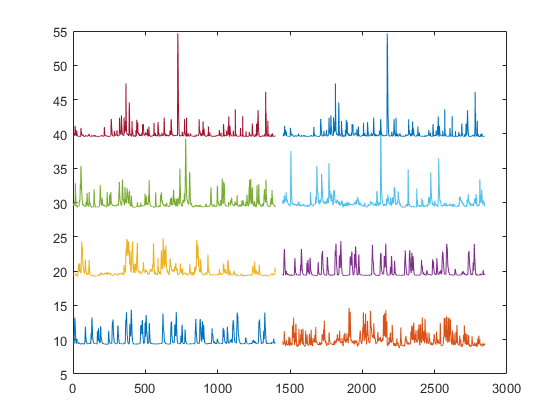

close all
p=3;m=1;% plot one example from 6 pair data
ca=zscore(E{p}{m}.dFFCalciumTraces);
[L,nc]=size(ca); s=floor(L/30); cabin=zeros(s,nc);
for t=1:s
    cabin(t,:)=mean(ca(30*(t-1)+1:30*t,:),1);
end
kurt{p,m}=kurtosis(cabin,1,1);
skew{p,m}=skewness(cabin,1,1);
grade{1}=[0 10 20 100];%kurtosis
grade{2}=[0 2 5 10];%skewness
figure(1) % activity dynamics
ind1=[];ind2=[];
for i=1:length(grade{1})
    [~,ind1(i)]=min(abs(kurt{p,m}-grade{1}(i)));[~,ind2(i)]=min(abs(skew{p,m}-grade{2}(i)));
    plot(1:size(cabin,1),cabin(:,ind1(i))+10*i)
    hold on
    plot(size(cabin,1)+51:2*size(cabin,1)+50,cabin(:,ind2(i))+10*i)
    % upper cells have higher kurtosis (sorted in the left) and skewness(sorted in the right)
end
hold off 

#### Method 1 - convert to binary 

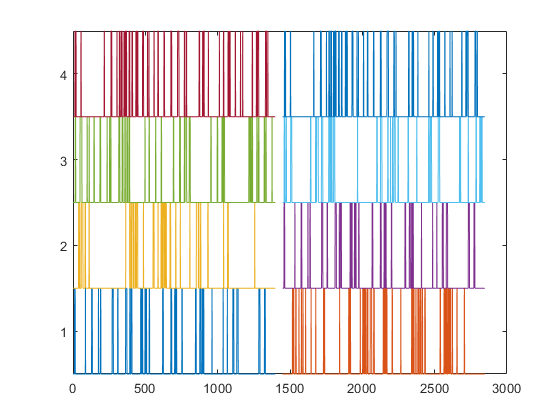

%% Convert the activity matrix into a binary one at 90% percentile
acc=sort(cabin,1,'ascend');
thre=acc(ceil(0.9*size(cabin,1)),:);
cabin_bi=cabin>=thre;
figure(2) 
for i=1:length(grade{1})
    plot(1:size(cabin,1),cabin_bi(:,ind1(i))+i-1)
    hold on
    plot(size(cabin,1)+51:2*size(cabin,1)+50,cabin_bi(:,ind2(i))+i-1)
    % upper cells have higher kurtosis (sorted in the left) and skewness(sorted in the right)
end
hold off;yticks(0.5:1:3.5); yticklabels(1:4)

- All cells will have same number of spikes. 

#### Method 2 - continuous between 0 and 1

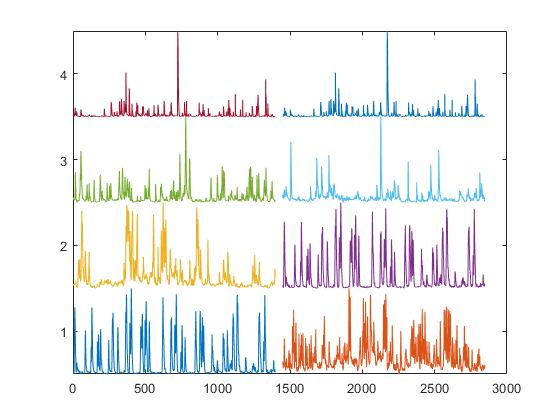

cabin_ct=(cabin-min(cabin))./(max(cabin)-min(cabin));
figure(3) 
for i=1:length(grade{1})
    plot(1:size(cabin,1),cabin_ct(:,ind1(i))+i-1)
    hold on
    plot(size(cabin,1)+51:2*size(cabin,1)+50,cabin_ct(:,ind2(i))+i-1)
    % upper cells have higher kurtosis (sorted in the left) and skewness(sorted in the right)
end
hold off;yticks(0.5:1:3.5); yticklabels(1:4)

- Cells with low kurtosis become amplified and cells with high kurtosis are suppressed 

#### Method 3 - continuous with cutoff (e.g. at 95%)

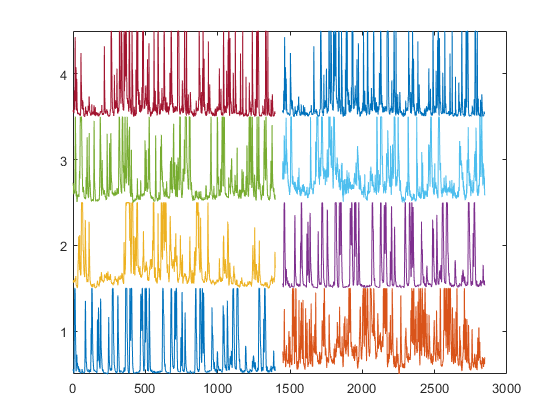

% set maximun at the 95% percentile
acc=sort(cabin,1,'ascend');
thre=acc(ceil(0.95*size(cabin,1)),:);
cabin_co=cabin;
for c=1:nc
    cabin_co(cabin(:,c)>=thre(c),c)=thre(c);
end
% normalize to 0-1
cabin_co=(cabin_co-min(cabin_co))./(max(cabin_co)-min(cabin_co));
figure(3) 
for i=1:length(grade{1})
    plot(1:size(cabin,1),cabin_co(:,ind1(i))+i-1)
    hold on
    plot(size(cabin,1)+51:2*size(cabin,1)+50,cabin_co(:,ind2(i))+i-1)
    % upper cells have higher kurtosis (sorted in the left) and skewness(sorted in the right)
end
hold off;yticks(0.5:1:3.5); yticklabels(1:4)

- Cell signals are similarly amplified and sparseness of signals remains 

- The highest 5% signal is lost 